syms x y th dx dy dth t

m = 0.5;
g = -9.81;

q = [x y th];
q = q(:);
q_dot = [dx dy dth];
q_dot = q_dot

$$q\_dot = \left(\begin{array}{ccc} \mathrm{dx} & \mathrm{dy} & \mathrm{dth} \end{array}\right)$$

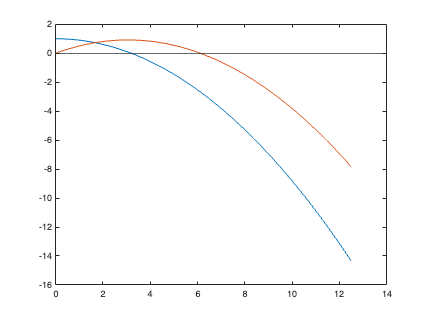

p = q;
v = jacobian(p,q).*q_dot;

PE = m*g.*q.*[0;1;0];
PE = sum(PE, 2);
KE = 1/2*m.*v.*v;
KE = sum(KE,2);

L = KE - PE;
L_vec = sum(L, 2);

dLdq = jacobian(L_vec,q);
dLdq = sum(dLdq, 2);
dLdq_dot = jacobian(L_vec,q_dot);
dLdq_dot = sum(dLdq_dot, 2);

eom = jacobian(dLdq_dot,t) - dLdq;

t0 = 0;
tf = 2.5;
tspan = linspace(t0, tf, 1e3);
[t_out, S_out] = ode45(@(t, S)odeFun(t, S, eom), tspan, [[0 1 0] [5 0 0]]);

plot(S_out(:,1),S_out(:,2))
hold on
yline(0)

[t_out, S_out] = ode45(@(t, S)odeFun(t, S, eom), tspan, [[0 0 0] [5 3 0]]);
plot(S_out(:,1),S_out(:,2))

function Sdot = odeFun(t, S, eom)
    e_num = matlabFunction(eom);
    Sdot = zeros(6,1);  % Changed to 6x1 column vector
  
    % First three elements are the positions
    Sdot(1:3) = S(4:6);
    % Last three elements are the velocities (from eom)
    Sdot(4:6) = e_num();
end